# SISO Communication System using QPSK Modulation 

In QPSK, each symbol is represented by 2 bits: the first bit (or odd bits) corresponds to the real part, and the second bit (or even bits) corresponds to the imaginary part of the symbol in 'symvec'. Each symbol energy Es is normalized to 1, and the Gray-coded symbols are as follows:

11→ $\frac{1}{\sqrt{2}}+i\frac{1}{\sqrt{2}}$

01→ $-\frac{1}{\sqrt{2}}+i\frac{1}{\sqrt{2}}$

11→ $-\frac{1}{\sqrt{2}}-i\frac{1}{\sqrt{2}}$

10→ $\frac{1}{\sqrt{2}}-i\frac{1}{\sqrt{2}}$

Gray mapping is used to minimize bit error rate by ensuring only one bit change between adjacent symbols.

Since each symbol is represented by 2 bits in QPSK modulation, the relationshop between symbol energy $E_s$ and bit energy $E_b$ is given by $E_s =kE_b$, where $k$ is the number of bits per symbol. For QPSK, k can be derived from $\log_2 M$, where M=4 is the number of distinct symbols. This gives the relation $E_s =2E_b$.

When converting from $\frac{E_s }{N_0 }\left(\textrm{dB}\right)$ to $\frac{E_b }{N_0 }\left(\textrm{dB}\right)$, we use the formula:


$$\frac{E_s }{N_0 }\left(\textrm{dB}\right)=\frac{E_b }{N_0 }\left(\textrm{dB}\right)+10\log_{10} \left(k\right)$$


For QPSK, k=2. $10\log_{10} \left(2\right)\approx 3\left(\textrm{dB}\right)$

Thus,


$$\frac{E_b }{N_0 }\left(\textrm{dB}\right)=\frac{E_s }{N_0 }\left(\textrm{dB}\right)-3\left(\textrm{dB}\right)$$


### **Simulation Setup**

M=4;              % QPSK
m=2;              % represent each symbol with 2 bits
Es=1;             % symbol energy
Nbits = 1e6;      % number of bits
Rs = 1;           % symbol rate
Fs = 4;           % sampling rate
sps = Fs/Rs;      % samples per symbol
EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
hrrc = rrc((-6:1/sps:6)',0.2,1); % Generate square-root raised cosine(rrc) pulse shaping filter 

% Tx
bitvec = randi([0,1],[Nbits,1]); % Generate random bits
symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);

### AWGN Channel, Sample Level

Now, we are passing our QPSK-modulated waveform through a root-raised-cosine (RRC) pulse shaping filter and then through an additive white Gaussian noise (AWGN) channel. We are sampling the signal over a range of SNR values from -3 dB to 20 dB. Our goal is to compare the bit error rate (BER) obtained from demodulation with the theoretical BER for Gray-mapped QPSK. The BER for QPSK is given by the following expression: 


$$\begin{array}{l}
\rho =Q\left(\sqrt{\frac{E_s }{N_0 }}\right)\\
{\textrm{BER}}_{\textrm{QPSK}} =\rho \cdot \left(1-\frac{1}{2}\rho \right)
\end{array}$$


The transmitted signal 'txvec' is obtained by upsampling the QPSK complex symbol vector 'symvec' and then convolving it with the RRC filter 'hrrc'.

The variable 'sig2' represents the noise power, $\sigma^2$. This value changes with SNR because $N_0$ (the noise power spectral density) is dependent on SNR. In the equation, $\frac{N_0 }{2}$ is used instead of $N_0$ since the noise power is equally distributed between the real and imaginary components of the signal for QPSK modulation.

The line "noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)))" generates complex noise with a standard normal distribution (mean=0, standard deviation=1). The noise is then scaled by 'sqrt(sig2)' to adjust for different SNR levels, ensuring that the noise power corresponds to the desired SNR. 

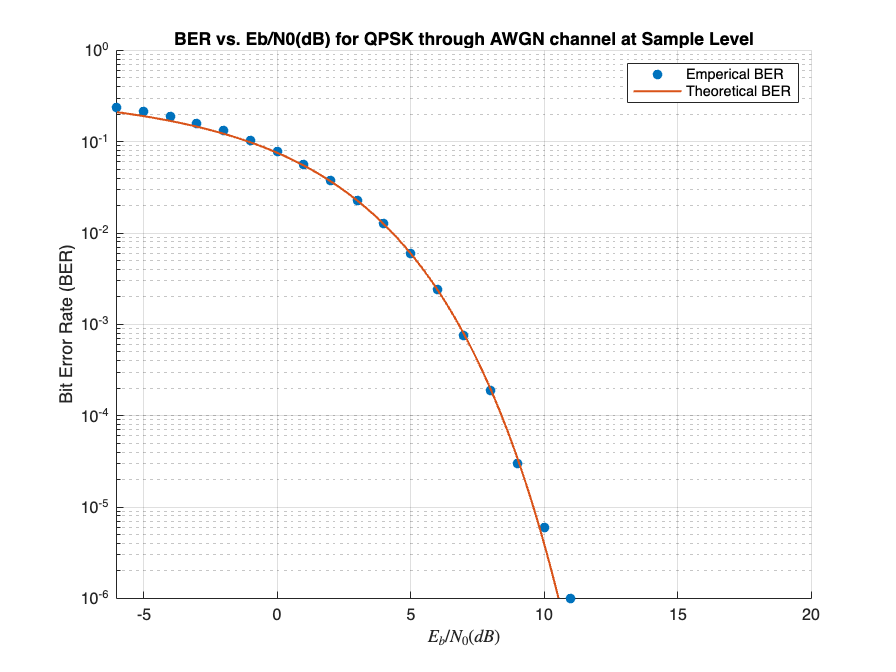

txvec = conv(upsample(symvec,sps),hrrc,'same');

% AWGN channel
% sample level
BER=zeros(1,length(EsN0dB));
for i=1:length(EsN0dB)
    
    sig2 = (N0(i)/2)*Fs;
    noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
    % Rx
    rxvec = txvec + noisevec; % length=(2e6x1)
    
    % Pass the received signal rxvec through a match filter, hrrc(T-t),
    matched_filter=conv(rxvec,hrrc,'same');            % y(t)=rxvex*hrrc
    matched_filter_sample=matched_filter(1:sps:end);   % downsample y(t)

    % Demodulation
    [decoded_syms,decoded_bits]=qpskdetect(matched_filter_sample);
    BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
end

% theoretical BER for gray-mapping QPSK
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2 - 3;
N02 = 10.^(-EsN0dB2/10);
BER_th=qfunc(sqrt(Es./N02)).*(1-0.5.*qfunc(sqrt(Es./N02)));

clf;    
figure; 
scatter(EbN0dB,BER,'filled')
set(gca,'yscale','log')
hold on
plot(EbN0dB2,BER_th,'LineWidth',1.3)
xlim([-6 20])
ylim([10e-7 1])
grid on
hold off
xlabel('$E_b/N_0 (dB)$', 'Interpreter', 'LaTex');
ylabel('Bit Error Rate (BER)');
title('BER vs. Eb/N0(dB) for QPSK through AWGN channel at Sample Level')
legend('Emperical BER','Theoretical BER')

### AWGN Channel, Symbol Level

Compare sample level simulation to symbol level simulation.

The results show that the performance is consistent across both symbol level and sample level simulations.

BER2=zeros(1,length(EsN0dB));

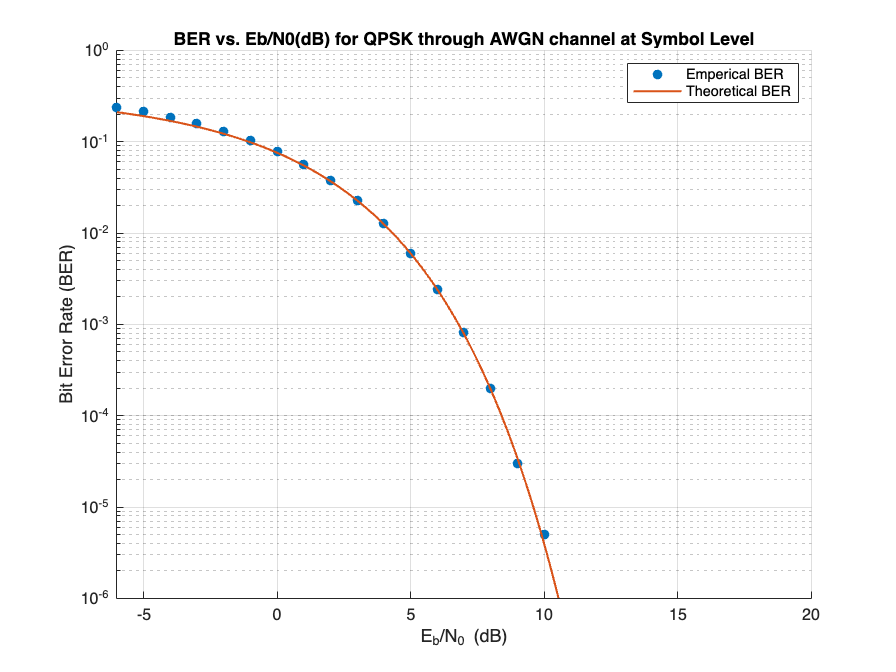

SER2=zeros(1,length(EsN0dB)); % symbol error rate

% symbol level
for i=1:length(EsN0dB)
    
    sig2 = N0(i)/2;  % notice that we don't have to multiply noise power with Fs here
    symnoise = sqrt(sig2)*complex(randn(size(symvec)),randn(size(symvec)));
    % Rx
    rxsymvec = symvec + symnoise; % length=(0.5e6x1)

    % Demodulation
    [decoded_syms2,decoded_bits2] = qpskdetect(rxsymvec);

    SER2(i) = sum(decoded_syms2~=symvec)/(Nbits/2);
    BER2(i) = sum(xor(decoded_bits2,bitvec))/Nbits;
end

% theoretical BER for gray-mapping QPSK
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2 - 3;
N02 = 10.^(-EsN0dB2/10);
BER_th=qfunc(sqrt(Es./N02)).*(1-0.5.*qfunc(sqrt(Es./N02)));

figure; 
scatter(EbN0dB,BER2,'filled')
set(gca,'yscale','log')
hold on
plot(EbN0dB2,BER_th,'LineWidth',1.3)
xlim([-6 20])
ylim([10e-7 1])
grid on
hold off
xlabel('E_b/N_0 (dB)', 'Interpreter', 'tex');
ylabel('Bit Error Rate (BER)');
title('BER vs. Eb/N0(dB) for QPSK through AWGN channel at Symbol Level')
legend('Emperical BER','Theoretical BER')

### Impulse Response of RRC Filter

'rrc' is the root-raised-cosine (RRC) pulse shaping filter function.

In the following equation, the roll-off factor is denoted by β, which corresponds to α as used in this project. $T_s =\frac{1}{R_s }$.

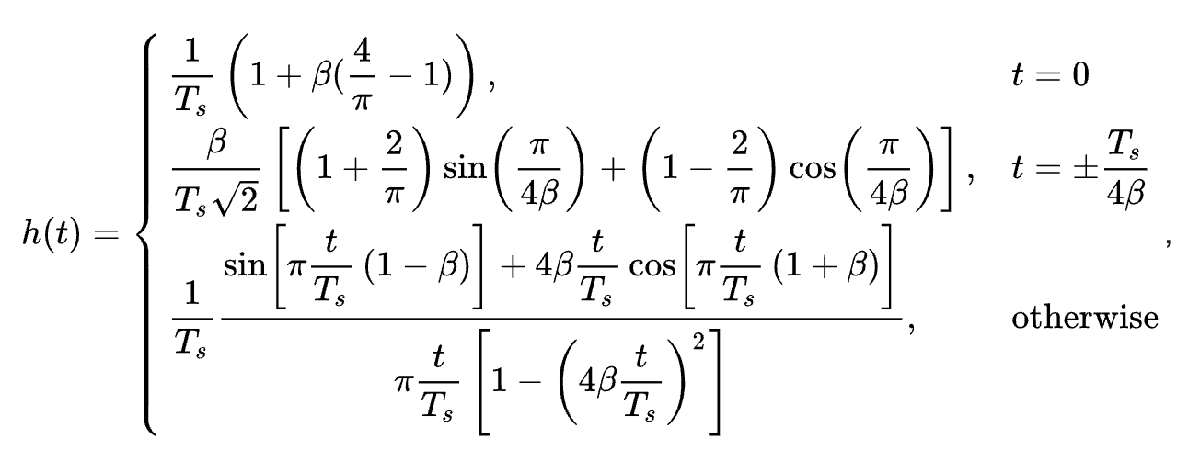

Equation1. Impulse Response of RRC Filter

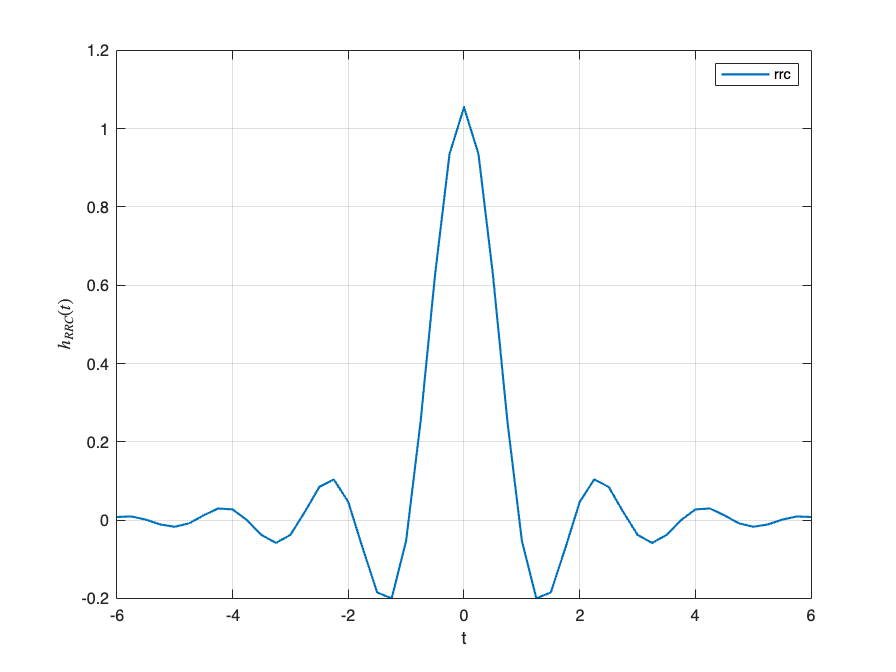

t=(-6:1/sps:6)';
alpha=0.2;
T=1/Rs;
hrrc=rrc(t,alpha,T);

figure;
plot(t,hrrc,'LineWidth',1.3)
grid on
xlabel('t')
ylabel('$h_{RRC}(t)$', 'Interpreter', 'latex')
legend('rrc')

### Effect of RRC Filter Roll-off Factor $\alpha$ on BER

Roll-factor $\alpha$ of RRC filter measures the additional bandwidth that the filter occupies beyond the Nyquist bandwidth in frequency domain. The Nyquist bandwidth is defined as $B_{\textrm{Nyquist}} =\frac{1}{2T}$, where $T=\frac{1}{R_s }$.

Although an RRC filter with a higher roll-off factor $\alpha$ requires more bandwidth, it has a smoother impulse response in the time domain (Figure 1), which reduces overlap between adjacent symbols and better prevents intersymbol interference (ISI). In contrast, an RRC filter with a lower roll-off factor $\alpha$ uses less bandwidth but has a sharper, more jittery impulse response, leading to higher BER due to increased ISI. 

Thus, there's a trade-off between bandwidth and BER: 

Higher roll-off factors improve BER at the cost of additional bandwidth, while lower roll-off factors conserve bandwidth but can result in higher BER due to greater ISI.

From the plot 'Impact of RRC Roll-off Factor on BER,' we observe that a roll-off factor of α = 0 results in a higher BER compared to α = 1. The result is consistent with the expectation based on our analysis.

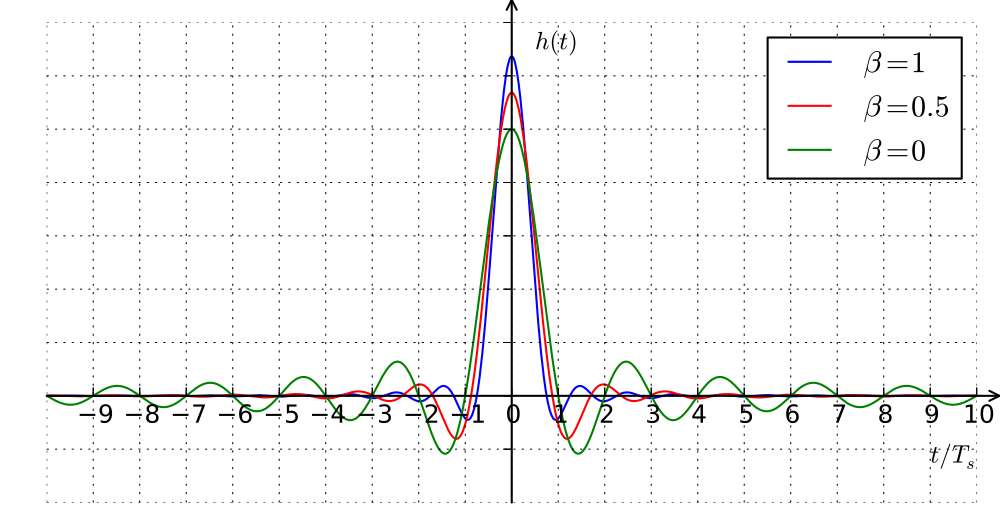

Figure 1. Impulse response of RRC filter in time domain (*Wikipedia: Root-raised-cosine filter, *[*https://en.wikipedia.org/wiki/Root-raised-cosine_filter*](https://en.wikipedia.org/wiki/Root-raised-cosine_filter)* )*

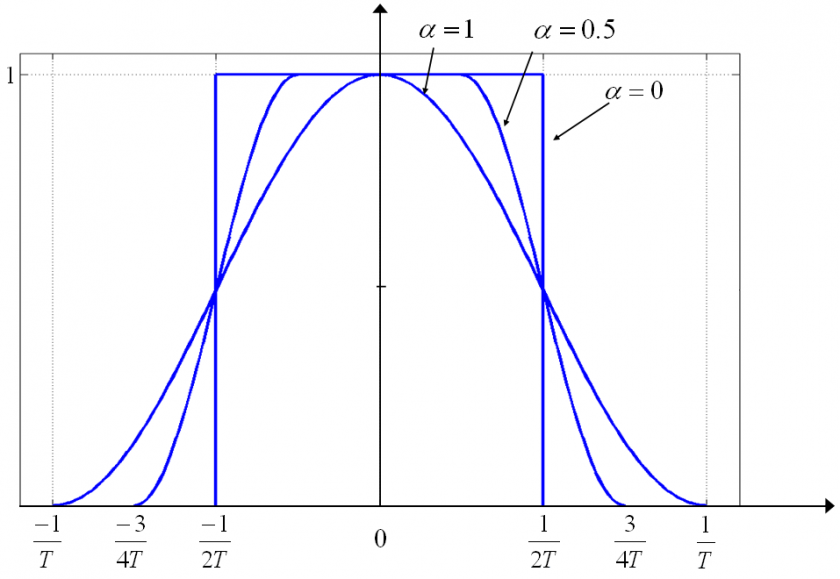

Figure 2. Impulse response of RRC filter in frequency domain *(Navipedia: Root-raised-cosine signals, *[*https://gssc.esa.int/navipedia/index.php/Square-Root_Raised_Cosine_Signals_%28SRRC%29*](https://gssc.esa.int/navipedia/index.php/Square-Root_Raised_Cosine_Signals_%28SRRC%29)* )*

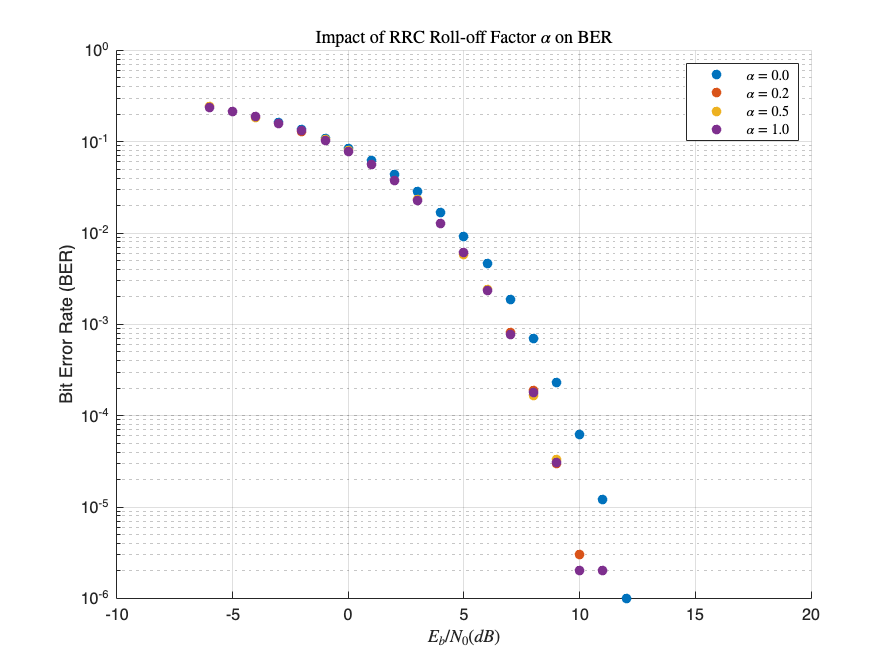

alpha=[0 0.2 0.5 1];
for k=1:length(alpha)
    hrrc = rrc((-6:1/sps:6)',alpha(k),1); 
    
    % Tx
    bitvec = randi([0,1],[Nbits,1]); % Generate random bits
    symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);
    txvec = conv(upsample(symvec,sps),hrrc,'same');
    
    BER=zeros(1,length(EsN0dB));
    for i=1:length(EsN0dB)
        
        sig2 = (N0(i)/2)*Fs;
        noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
        % Rx
        rxvec = txvec + noisevec; % length=(2e6x1)
        
        matched_filter=conv(rxvec,hrrc,'same');            % y(t)=rxvex*hrrc
        matched_filter_sample=matched_filter(1:sps:end);   % downsample y(t)
    
        % Demodulation
        [syms,decoded_bits]=qpskdetect(matched_filter_sample);
        BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
    end
    scatter(EbN0dB,BER,'filled','DisplayName',sprintf('$\\alpha=%.1f$', alpha(k)));
    hold on
end

set(gca,'yscale','log')
grid on
hold off
xlabel('$E_b/N_0 (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('Impact of RRC Roll-off Factor $\alpha$ on BER', 'Interpreter', 'latex');
legend('Interpreter', 'latex')

### Comparison of BER perdormance for RRC Filters with Different Roll-off factor $\alpha$ but Equal Bandwidth

In this section, we're comparing two RRC filters with roll off factor $\alpha =0$ and $\alpha =1$ with the same bandwidth. To achieve this, we double the bandwidth impulse reponse with $\alpha =0$ (see the figure). This increase in bandwidth results in a doubling of symbol rate. To accomodate this change, we also double the sampling rate (Fs). This adjustment ensure that both cases have the same number of samples per symbol (sps=Fs/Rs) and consistent time resolution for the waveform. 

*case 1: *

- *Roll off factor: *$\alpha =0$

- Symbol rate: ${2R}_s$

- Nyquist bandwidth: $B_{\textrm{Nyquist}} =$$\frac{2}{T}$

- Bandwidth used: $\frac{2}{T}$

case 2:

- *Roll off factor: *$\alpha =1$

- Symbol rate: $R_s$

- Nyquist bandwidth: $B_{\textrm{Nyquist}} =$$\frac{1}{T}$

- Bandwidth used: $\frac{2}{T}$

*Assumption:* 

Given that rect() ($\alpha =0$) impulse response has a more jittery tail in time domain, it is expected to exhibit a higher BER compered to RRC filter with roll off factor of $\alpha =1$.

*Question:* 

How does BER change when the symbol rate is doubled with fixed roll off factor $\alpha =0$? Compare BERs of RRC filter with symbol rate Rs to that of an RRC filter with synbol rate 2Rs.

clf;
figure;
Nbits1 = 1e6;    
Nbits2 = 1e6;
Nbitss = [Nbits1 Nbits2];
Rs1 = 1; 
Rs2 = 2;
T1=1/Rs1;
T2=1/Rs2;
Fs1 = 4;   
Fs2 = 8;
Fss = [Fs1 Fs2];
sps1 = Fs1/Rs1;     
sps2 = Fs2/Rs2;
spss=[sps1 sps2]; % sps1 and sps2 should be the same
alpha1=0;
alpha2=1;
EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
hrrc1 = rrc((-6:1/sps1:6)',alpha1,T1);  % RRC filter for case 1
hrrc2 = rrc((-6:1/sps2:6)',alpha2,T2);  % RRC filter for case 2
hrrcs=[hrrc1 hrrc2];

cases=[1 2];

figure;
for k=1:length(cases)
    % Tx
    bitvec = randi([0,1],[Nbitss(k),1]); 
    symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);
    txvec = conv(upsample(symvec,spss(k)),hrrcs(:,k)','same');
    BER=zeros(1,length(EsN0dB));
    for i=1:length(EsN0dB)
        
        sig2 = (N0(i)/2)*Fss(k);
        noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
        % Rx
        rxvec = txvec + noisevec; % length=(2e6x1)
        
        % Pass the received signal rxvec through a match filter, hrrc(T-t),
        matched_filter=conv(rxvec,hrrcs(:,k)','same');            % y(t)=rxvex*hrrc
        matched_filter_sample=matched_filter(1:spss(k):end);   % downsample y(t)
    
        % Demodulation
        [syms,decoded_bits]=qpskdetect(matched_filter_sample);
        BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
    end
    scatter(EbN0dB,BER,'filled','DisplayName',sprintf('case %d',cases(k)))
    hold on
end
    


set(gca,'yscale','log')
hold off
xlim([-6 20])
ylim([10e-7 1])
grid on

xlabel('$E_b/N_0 (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('')
legend;

### Slow Flat Fading Channel (Sample Level Simulation)

When a signal is transmitted from a transmitter to a receiver, it often travels through multiple paths, a phenomenon known as multipath propagation. Each path may introduce different levels of attenuation and phase shifts. When these signals converge at the receiver, their alignment in amplitude and phase can lead to either constructive or destructive interference, resulting in fluctuations in signal strength over time called "fading." This effect can be quantified by the fading channel coefficient, h.

***Fading Channel Coefficient: ***$h=a\cdot e^{-j\theta } =x+\textrm{jy}$, which $a=|h|$ is the amplitude and $\theta =\angle h$ is the phase of fading channel coefficient.


$$a=\sqrt{x^2 +y^2 }$$



$$\theta =\tan^{-1} \left(\frac{y}{x}\right)$$


***Flat Fading: ***A flat fading channel exhibits uniform attenuation across the entire bandwidth of the transmitted signal, affecting all frequency components equally. This means the signal is transmitted without distortion, though it may be uniformly attenuated or amplified. (Distortion occurs when different frequency components of the transmitted signal experience different levels of attenuation and phase shift in frequency domain, altering the signal's original shape.)

***Slow Fading:*** Fading channel coefficient, h, varies slowly over time. Happens when obstacles or transimtter and receiver either move slowly or remain static.

'sigfad': $|h|$

'fadingalpha': $h=|h|\cdot e^{-j\theta }$

fadingalpha = sigfad(n)*complex(randn(1),rand(1));

In the above code, we generate a random fading channel coefficient h with its amplitude 'sigfad' |h|. We then multiply |h| by a randomly generated complex number, where both the real and imaginary parts follow a standard normal distribution, ensuring the  phase is uniformly distributed over $-\pi$ to $\pi$.

Suppose we have a complex $Z=X+\textrm{jY}$, $X~N\left(0,1\right)$ and $Y~N\left(0,1\right)$, and X is independent of Y


$$f_{\textrm{XY}} \left(x,y\right)=f_X \left(x\right)\cdot f_Y \left(y\right)=\frac{1}{\sqrt{2\pi }}e^{\frac{-x^2 }{2}} \cdot \frac{1}{\sqrt{2\pi }}e^{\frac{-y^2 }{2}} =\frac{1}{2\pi }e^{\frac{-\left(x^2 +y^2 \right)}{2}}$$



$$f_{A\Theta } \left(a,\theta \right)=\frac{a}{2\pi }e^{\frac{-a^2 }{2}}$$


$f_A \left(a\right)=\int_{-\pi }^{\pi } \frac{a}{2\pi }e^{\frac{-a^2 }{2}} d\theta =2a{\cdot e}^{-a^2 }$...Rayleigh distribution

$f_{\Theta } \left(\theta \right)=$$\int_0^{\infty } \frac{a}{2\pi }e^{\frac{-a^2 }{2}} \textrm{da}=\frac{1}{2\pi }$...uniform distribution, $\left\lbrack -\pi ,\pi \right\rbrack$

***Coherence Bandwidth:***

$B_c$: coherence bandwidth (flat portion of channel bandwidth)

$B_s$: signal bandwidth

(a) $B_s$<$B_c$ $\longrightarrow$Flat fading without distortion             (b) $B_s$>$B_c$ $\longrightarrow$Frequency selective channel with distortion

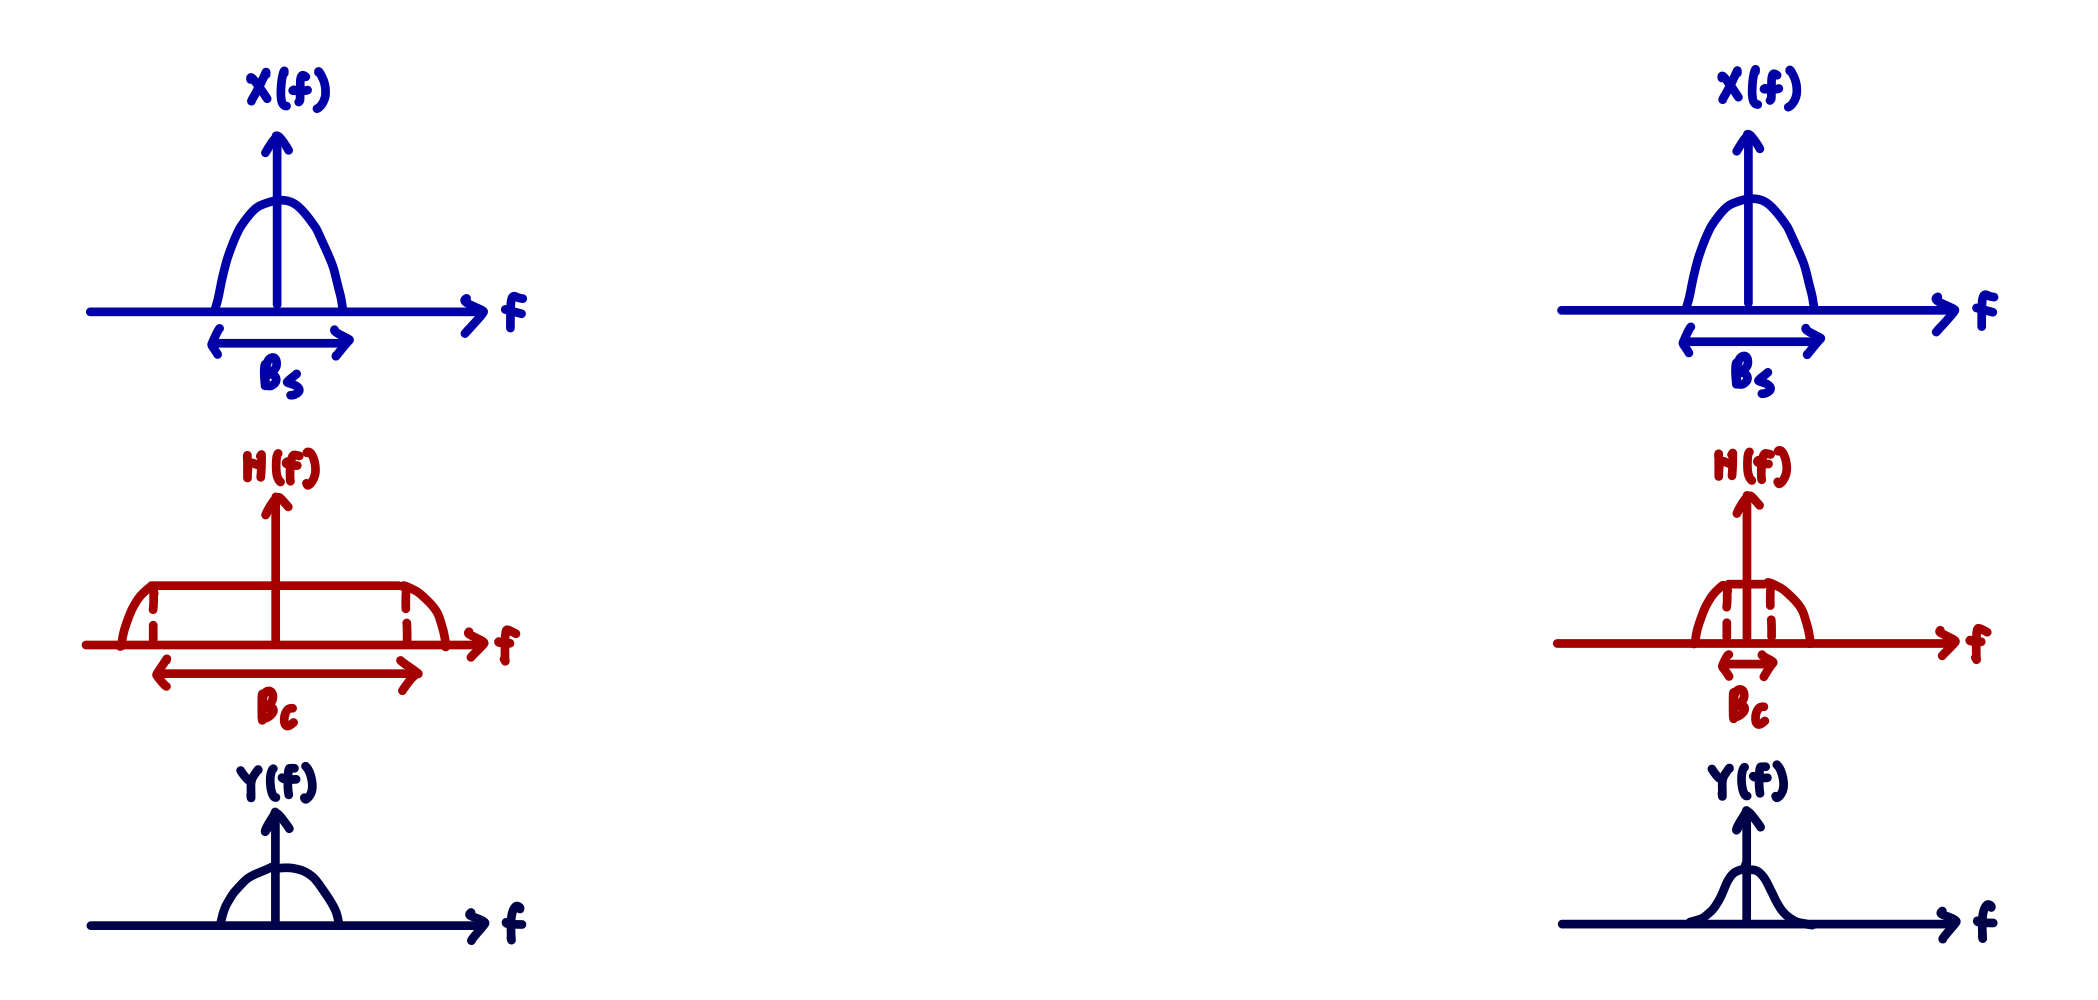

In frequency domain, we have $|Y|=|X|\cdot |H|$, where $|X|$ and $|Y|$ are transmitted and received signals, and $|H|$ is the impulse response of the channel. In case (a), the signal bandwidth $B_s$ is within the flat portion of channel bandwidth $B_c$, so all frequency components of the signal are attenuated equally as they pass through the channel. As a result, no distortion occurs. In case (b), since signal bandwidth $B_s$ is wider than the channel bandwidth $B_c$, the transmitted signal gets distorted.

***Phase Compensation:***

mfout = conv(rxvecfad*exp(-1i*angle(fadingalpha)),hrrc,'same')/Fs;

In this step, we correct the phase shift introduced by channel fading during transmission. This process, known as phase compensation, involves applying the inverse of the phase shift caused by the channel to the received signal.

Compare experimental result with theoretical value:

SNR affected by fading channel: ${\textrm{SNR}}_{\textrm{fading}} =\frac{{|h|}^2 \cdot E_s }{N_0 }={|h|}^2 \cdot \textrm{SNR}$

Theoretical value of BER with fading channel: ${\textrm{BER}}_{\textrm{thm}} =\frac{1}{2}\cdot \left(1-\sqrt{\frac{{\textrm{SNR}}_{\textrm{fading}} }{1\ldotp 5+{\textrm{SNR}}_{\textrm{fading}} }}\right)$

%% Flat fading
% sample-level simulation
clf;
figure;
Nbits=1e3;
Rs=1;
T=1/Rs;
Fs=4;
sps=Fs/Rs;
alpha=0.2;  % roll-off factor
hrrc=rrc((-6:1/sps:6)',alpha,T);

EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2-3; 
N02 = 10.^(-EsN0dB2/10);

bitvec=randi([0,1],[Nbits,1]);
symvec=(1/sqrt(2))*complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1);
txvec = conv(upsample(symvec,sps),hrrc,'same');

sigfad = [0.1 0.5 1];   % |h|: amplitude of fading channel coefficent

ser3=zeros(1,length(EsN0dB));
ber3=zeros(1,length(EsN0dB));

nruns = 100;
for n=1:length(sigfad)

    for i=1:length(EsN0dB)
        sig2 = N0(i)*Fs/2;
        total_symbol_error = 0;
        total_bit_error = 0;
        for k = 1:nruns
            noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
            fadingalpha = sigfad(n)*complex(randn(1),rand(1));  % h=|h|*exp(i*theta), theta=phase of h
            rxvecfad = fadingalpha * txvec + noisevec;
            mfout = conv(rxvecfad*exp(-1i*angle(fadingalpha)),hrrc,'same')/Fs; % phase compensation
            mfsamp = mfout(1:sps:end);
            [detsymvec,detbitvec] = qpskdetect(mfsamp);
            total_symbol_error = total_symbol_error + sum(detsymvec~=symvec)/(Nbits/2);
            total_bit_error = total_bit_error + sum(xor(detbitvec,bitvec))/Nbits;
        end
        ser3(i) = total_symbol_error/nruns;
        ber3(i) = total_bit_error/nruns;
    end
    
    scatter(EbN0dB,ber3,'filled','DisplayName',sprintf('experimental BER, |h|= %.1f',sigfad(n)));
    hold on
end

% theoretical BER for QPSK modulation with flat fading channel
for n=1:length(sigfad)
    SNR_fad=sigfad(n)^2*Es./N02; % SNRs affected by fading channel
    BER_th=0.5*(1-sqrt(SNR_fad./(1.5+SNR_fad)));
    plot(EbN0dB2,BER_th,'LineWidth',1.3,'DisplayName',sprintf('theoretical BER, |h|= %.1f',sigfad(n)))
end


set(gca,'yscale','log')
hold off
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('Effect of Fading Channel Coefficient on BER')
legend("Position", [0.1641 0.2503 0.2661, 0.1583]);

### Slow Flat Fading Channel (Symbol Level Simulation)

Compare sample level simulation to symbol level simulation.

The results show that the performance is consistent across both symbol level and sample level simulations.

%% Flat fading
% symbol-level simulation
clf;
figure;

bitvec=randi([0,1],[Nbits,1]);
symvec=(1/sqrt(2))*complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1);

sigfad = [0.1 0.5 1];   % |h|: amplitude of fading channel coefficent

ser4=zeros(1,length(EsN0dB));
ber4=zeros(1,length(EsN0dB));

nruns = 100;
for n=1:length(sigfad)

    for i=1:length(EsN0dB)
        sig2 = N0(i)/2;
        total_symbol_error = 0;
        total_bit_error = 0;
        for k = 1:nruns
            noisevec = sqrt(sig2)*complex(randn(size(symvec)),randn(size(symvec)));
            fadingalpha = sigfad(n)*complex(randn(1),rand(1));  % h=|h|*exp(i*theta), theta=phase of h
            rxvecfad = fadingalpha * symvec + noisevec;
            % Phase compensation
            rxvecfad = rxvecfad*exp(-1i*angle(fadingalpha));
            [detsymvec,detbitvec] = qpskdetect(rxvecfad);
            total_symbol_error = total_symbol_error + sum(detsymvec~=symvec)/(Nbits/2);
            total_bit_error = total_bit_error + sum(xor(detbitvec,bitvec))/Nbits;
        end
        ser4(i) = total_symbol_error/nruns;
        ber4(i) = total_bit_error/nruns;
    end
    
    scatter(EbN0dB,ber4,'filled','DisplayName',sprintf('experimental BER, |h|= %.1f',sigfad(n)));
    hold on
end

% theoretical BER for QPSK modulation with flat fading channel
for n=1:length(sigfad)
    SNR_fad=sigfad(n)^2*Es./N02; % SNRs affected by fading channel
    BER_th=0.5*(1-sqrt(SNR_fad./(1.5+SNR_fad)));
    plot(EbN0dB2,BER_th,'LineWidth',1.3,'DisplayName',sprintf('theoretical BER, |h|= %.1f',sigfad(n)))
end


set(gca,'yscale','log')
hold off
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('Effect of Fading Channel Coefficient on BER')
legend("Position", [0.1641 0.2503 0.2661, 0.1583]);

# 2x2 MIMO System

### Perfect CSI at Rx only: Zero-Forcing (ZF) Equalizer

Perfect channel state information (CSI): The receiver knows the exact channel conditions (ex: channel matrix H)

Suppose the received signal is represented as: $y=\textrm{Hx}+n$, where x and y are the transimtted and received signal, n is the Gaussian noise, and H is the channel matrix containing channel fading coefficients $h_{\textrm{ij}}$ of each pair of Tx/Rx channel.

Now we want to estimate the transmit signal x with Zero Forcing (ZF) equalizer: ${\hat{x} }_{\textrm{ZF}} ={\left(H^H H\right)}^{-1} H^H y$, $W_{\textrm{ZF}} ={\left(H^H H\right)}^{-1} H^H$

ZF equalizer applies the inverse frequency response of the channel to the received signal y to recover the transmitted signal x.

In the frequency domain, the Zero Forcing equalizer aims to recover the transmitted signal $X\left(f\right)$ from the received signal $Y\left(f\right)$ by applying an inverse filter $\frac{1}{H\left(f\right)}$�:

$\hat{X} \left(f\right)=\frac{1}{H\left(f\right)}Y\left(f\right)$, where $Y\left(f\right)=X\left(f\right)H\left(f\right)+\textrm{noise}$ is the received signal


$$\hat{X} \left(f\right)=$$

$$\frac{1}{H\left(f\right)}\left\lbrace X\left(f\right)H\left(f\right)+\textrm{noise}\right\rbrace =X\left(f\right)+\frac{1}{H\left(f\right)}\cdot \textrm{noise}$$


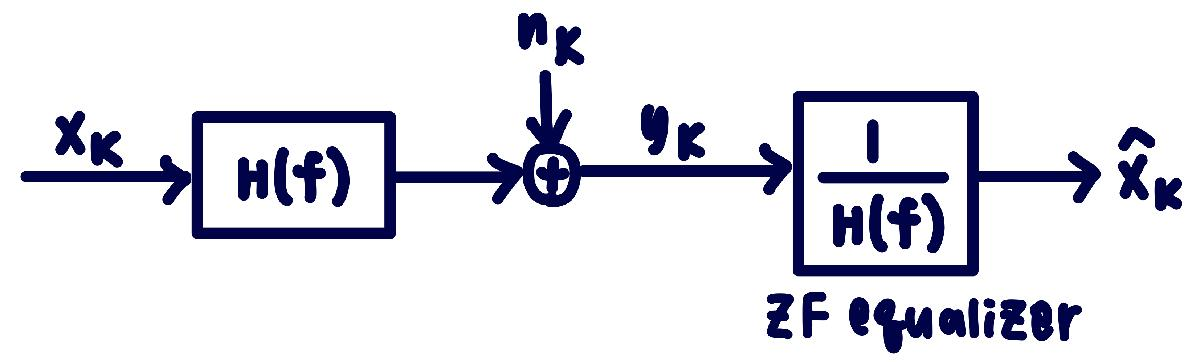

***Limitations of ZF equalizer: ***

The ZF equalizer can amplify noise significantly, especially when the channel response $H\left(f\right)$ is very small or approaches zero (deep fades or nulls). In these conditions, the term $\frac{1}{H\left(f\right)}$� becomes very large, leading to substantial noise amplification. This effect is exacerbated at low SNR, where the noise level is already high, further degrading the system performance.

% Perfect CSI at Rx only
% Zero Forcing (ZF) MIMO receiver
clf;

Nbits=1e4;
Es=1;
Rs=1;
Fs=4;
T=1/Rs;
sps=Fs/Rs;

EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);

Nt = 2; Nr = 2; % number of tx and rx antennas
sigfad = 1;

bitvec = randi([0,1],[Nbits,1]);
symvec = (1/sqrt(2))*complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1); % (1x5000)
txsyms = reshape(symvec,floor([Nt,length(symvec)/Nt]));  % X=[x1 x2]'
numCol = length(txsyms(1,:));
ser5=zeros(1,length(EsN0dB));
ber5=zeros(1,length(EsN0dB));
nruns=100;

for i=1:length(EsN0dB)
    total_symbol_error=0;
    total_bit_error=0;
    for k=1:nruns
        y=zeros(size(txsyms));
        x_ZF=zeros(size(txsyms));
        for col=1:numCol
            noise = sqrt(N0(i))*complex(randn(Nr,1),randn(Nr,1)); % (2x1)
            H = sigfad*complex(randn(Nr,Nt),randn(Nr,Nt)); % channel matrix (2x2)
            y(:,col)=H*txsyms(:,col)+noise;

            % Use Zero Forcing estimation to recover transmit symbols
            x_ZF(:,col)=(H'*H)\(H'*y(:,col));
        end
        x_ZF=reshape(x_ZF,[1,length(symvec)]);
        [decoded_symbol_vector,decoded_bit_vector]=qpskdetect(x_ZF);
        total_symbol_error = total_symbol_error+sum(decoded_symbol_vector~=symvec')/(Nbits/2);
        total_bit_error = total_bit_error+sum(xor(bitvec,decoded_bit_vector))/Nbits;
    end
    ser5(i)=total_symbol_error/nruns;
    ber5(i)=total_bit_error/nruns;
end


figure;
scatter(EbN0dB,ber5,'filled');
set(gca,'yscale','log')
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER of Perfect CSI at Receiver with Zero-Forcing Decoding');

### Perfect CSI at Rx only: Linear Minimum Mean-Square-Error (LMMSE) Equalizer

Now, we estimate transmit signal x with Linear Minimize Mean Square Error (LMMSE) equalizer: ${\hat{x} }_{\textrm{LMMSE}} ={\left(H^H H+\frac{1}{\textrm{SNR}}I\right)}^{-1} H^H y$

$W_{\textrm{LMMSE}} ={\left(H^H H+\frac{1}{\textrm{SNR}}I\right)}^{-1} H^H$, $\frac{1}{\textrm{SNR}}=\frac{{\sigma_n }^2 }{{\sigma_x }^2 }$

The LMMSE equalizer balances the trade-off between recovering the transmitted signal and mitigating noise amplification. It scales the noise term based on SNR, which helps to reduce noise term compared to ZF equalizer, particularly in low SNR conditions. 

(1) At high SNR, LMMSE equalizer performs similar as ZF equalizer: $\frac{1}{\textrm{SNR}}\to 0$, $W_{\textrm{LMMSE}} \approx W_{\textrm{ZF}} ={\left(H^H H\right)}^{-1} H^H$

(2) At low SNR, $W_{\textrm{LMMSE}} \approx$${\left(\frac{1}{\textrm{SNR}}I\right)}^{-1} H^H =\textrm{SNR}\cdot H^H$

${\hat{x} }_{\textrm{LMMSE}} =$$W_{\textrm{LMMSE}}$$\cdot y=$($\textrm{SNR}\cdot H^H$)$\cdot \left(H\cdot x+\textrm{noise}\right)=\textrm{SNR}\cdot x+$$\textrm{SNR}\cdot H^H \cdot \textrm{noise}$

Appying the LMMSE equalizer scales down the noise term at low SNR. While this scaling also reduces the amplitude of the recovered transmitted signal x, it significantly lowers the bit error rate by reducing the noise amplification that occurs at low SNR.

% convert SNR to linear scale
SNR=10.^(EsN0dB./10);
ser6=zeros(1,length(EsN0dB));
ber6=zeros(1,length(EsN0dB));
nruns=100;

for i=1:length(EsN0dB)
    total_symbol_error=0;
    total_bit_error=0;
    for k=1:nruns
        y=zeros(size(txsyms));
        x_ZF=zeros(size(txsyms));
        for col=1:numCol
            noise = sqrt(N0(i))*complex(randn(Nr,1),randn(Nr,1)); % (2x1)
            H = sigfad*complex(randn(Nr,Nt),randn(Nr,Nt)); % channel matrix (2x2)
            y(:,col)=H*txsyms(:,col)+noise;

            % Use Zero Forcing estimation to recover transmit symbols
            x_ZF(:,col)=(H'*H+(1/SNR(i))*eye(Nt))\(H'*y(:,col));
        end
        x_ZF=reshape(x_ZF,[1,length(symvec)]);
        [decoded_symbol_vector,decoded_bit_vector]=qpskdetect(x_ZF);
        total_symbol_error = total_symbol_error+sum(decoded_symbol_vector~=symvec')/(Nbits/2);
        total_bit_error = total_bit_error+sum(xor(bitvec,decoded_bit_vector))/Nbits;
    end
    ser6(i)=total_symbol_error/nruns;
    ber6(i)=total_bit_error/nruns;
end


figure;
scatter(EbN0dB,ber6,'filled','r');
set(gca,'yscale','log')
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER of Perfect CSI at Receiver with LMMSE Decoding');

#### Comparison of BER for ZF and LMMSE Equalizers

The result below shows that the LMMSE equalizer generally has a lower SNR than the ZF equalizer due to its noise scaling. At very high SNR, where the noise becomes extremely small, both equalizers are expected to perform similarly, resulting in converging BERs.

load('/Users/tracychiayu/Documents/132A project/data/BER_ZF_equalizer.mat');
load('/Users/tracychiayu/Documents/132A project/data/BER_LMMSE_equalizer.mat');

figure;
scatter(EbN0dB,ber5,'filled','DisplayName','ZF equalizer');
hold on
scatter(EbN0dB,ber6,'filled','DisplayName','LMMSE equalizer');
set(gca,'yscale','log')
xlim([-6 17])
ylim([1e-3 1])
grid on
hold off

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER Comparison: ZF vs. LMMSE Equalizers');
legend;

### Perfect CSI at Tx and Rx: MIMO for Throughput

In a MIMO system designed for throughput, the goal is to increase the data rate by transmitting different data streams simultaneously through multiple independent channels. By performing Singular Value Decomposition (SVD) on the channel matrix H, we can decompose H into $H=U\Sigma V^H$, where U and V are unitary matrices, and $\Sigma$ is a diagonal matrix containing the singular values of H. The matrix V is used to precode the transmitted signals, transforming the original MIMO system into a set of parallel independent channels with channel coeffient $\sigma_i$. This enables simultaneous transmission of multiple data streams through parallel channels, increasing the system's data rate. The receiver then uses the matrix $U^H$ to post-process the received signal $\tilde{y}$, allowing signal decoding.

***Singular Value Decomposition (SVD): ***$H=U\Sigma V^H$

$U$ is orthonormal and unitary. Suppose $U=\left\lbrack u_1 \;\ldotp \ldotp \ldotp u_r \right\rbrack$ where $u_i$ is column vector. $u_i \cdot u_j =0\;\;\textrm{if}\;\;i\not= j$ and $u_i \cdot u_j =1\;\;\textrm{if}\;\;i=j$. $U^H U=UU^H =I$

$\Sigma$ is a diagonal matrix. For 2x2 MIMO system, $\Sigma =\left\lbrack \begin{array}{cc}
\sigma_1  & 0\\
0 & \sigma_2 
\end{array}\right\rbrack$ where $\sigma_1 \ge$$\sigma_2 \ge 0$ and ${\sigma_i }^{\prime } s$ are singular values (non-negative real number) of H 

$V$ is the unitary matrix, where $V^H V=VV^H =I$ and $V^{-1} =V^H$

Now, we want to transform the orginal MIMO system $\bar{y} =H\bar{x} +\bar{n}$ into a set of parallel indepedent channels.

***Process:***

- Precode the transmitted signal $\bar{x}$ using $V$ matrix from $\textrm{svd}\left(H\right)$: $\tilde{x} =V\bar{x}$

- Pass the precode signal $\tilde{x}$ through the channel. The receiced signal is denoted as $\tilde{y} =H\tilde{x} +\textrm{noise}$

- Post-processing received signal $\tilde{y}$ by $U^H$: 

             
$$\tilde{y} =H\tilde{x} +\textrm{noise}=\left(U\Sigma V^H \right)\left(V\bar{x} \right)+\textrm{noise}=U\Sigma \bar{x} +\textrm{noise}$$


             
$$U^H \tilde{y} =$$

$$U^H$$

$$U\Sigma \bar{x} +U^H \cdot \textrm{noise}$$


            
$$\bar{y} =$$

$$\Sigma \bar{x} +U^H \cdot \textrm{noise}$$


            
$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\sigma_1  & 0\\
0 & \sigma_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
n_1 \\
n_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sigma_1 x_1 +n_1 \\
\sigma_2 x_2 +n_2 
\end{array}\right\rbrack$$


By precoding the transmitted signal $\bar{x}$ using the matrix $V$ from the $\textrm{svd}\left(H\right)$, we transform the original MIMO system into a set of parallel independent channels. 

Nbits=1e4;
EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);

Nt = 2; Nr = 2; % number of tx and rx antennas 
sigfad = 1;     % |h|
bitvec=randi([0,1],[Nbits,1]);
symvec=complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2); % 1x5000
txsyms = reshape(symvec,floor([Nt,length(symvec)/Nt]));          % 2x2500
numCol = length(txsyms(1,:)); % 2500

% perfect CSI at Tx and Rx - MIMO for throughput
nrun=100;
ser7=zeros(1,length(EsN0dB));
ber7=zeros(1,length(EsN0dB));
for i=1:length(EsN0dB)
    total_bit_error=0;
    total_symbol_error=0;
    for k=1:nruns
        H = sigfad*complex(randn(Nr,Nt),randn(Nr,Nt)); % channel matrix
        [U,S,V] = svd(H); 
        rxsyms=zeros(size(txsyms));
        for col=1:numCol

            noise=sqrt(N0(i))*complex(randn(Nr,1),randn(Nr,1));
            xtilde = V*txsyms(:,col) ; % precode txsyms
            ytilde = H*xtilde+noise;
            rxsyms(:,col)=U'*ytilde; % post-processing

        end

        rxsyms=reshape(rxsyms,[1,length(symvec)]);
        [decoded_symbol_vector,decoded_bit_vector]=qpskdetect(rxsyms);
        total_symbol_error=total_symbol_error+sum(decoded_symbol_vector~=symvec')/(Nbits/2);
        total_bit_error=total_bit_error+sum(xor(decoded_bit_vector,bitvec))/Nbits;
    end
    ser7(i)=total_symbol_error/nruns;
    ber7(i)=total_bit_error/nruns;
end

figure;
scatter(EbN0dB,ber7,'filled');
set(gca,'yscale','log')
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER of Perfect CSI Tx/Rx MIMO for Throughput');

### Perfect CSI at Tx and Rx: MIMO for Diversity

In the previous section, we increased the data rate by transmitting different data streams through a MIMO system. Now, we aim to enhance reliability by transmitting the same data across multiple independent channels, each experiencing different fading effects. By summing the signals received from these channels, the likelihood of the transmitted signal undergoing deep fade is reduced, thereby lowering the bit error rate.

txsyms = repmat(symvec,[1,2]).'; 

We duplicate the 5000x1 symbol vector 'symvec' to create a 2x5000 transmitted matrix 'txsyms', which is then sent through two independent channels.

rxvec=sum(y).';

'rxvec' is a 5000x1 vector that sums the received signals for each duplicated symbol across multiple channels, which helps enhance the signal and reduce the impact of deep fading on each symbol.

% perfect CSI at Tx and Rx - MIMO for diversity
Nbits=1e4;
bitvec=randi([0,1],[Nbits,1]);
symvec=complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2); % 5000x1
txsyms = repmat(symvec,[1,2]).';                                 % 2x5000 replicate the transmitted symbols
numCol=length(symvec);

ser8=zeros(1,length(EsN0dB));
ber8=zeros(1,length(EsN0dB));
nruns=100;
for i=1:length(EsN0dB)
    total_bit_error=0;
    total_symbol_error=0;
    for k=1:nruns
        H=sigfad*complex(randn(Nt,Nr),randn(Nt,Nr));
        [U,S,V]=svd(H);
        y=zeros(size(txsyms));
        for col=1:numCol
            noise=sqrt(N0(i))*complex(randn(Nr,1),randn(Nr,1));
            xtilde=V*txsyms(:,col);  % precode txsyms
            ytilde=H*xtilde+noise;
            y(:,col)=U'*ytilde;      % post-process ytilde
        end
        rxvec=sum(y).';  % 5000x1                
        [decoded_symbol_vector,decoded_bit_vector]=qpskdetect(rxvec);
        total_bit_error=total_bit_error+sum(xor(bitvec,decoded_bit_vector))/Nbits;
        total_symbol_error=total_symbol_error+sum(symvec~=decoded_symbol_vector)/(Nbits/2);
    end
    ser8(i) = total_symbol_error/nruns;
    ber8(i) = total_bit_error/nruns;
end

figure;
scatter(EbN0dB,ber8,'filled');
set(gca,'yscale','log')
xlim([-6 17])
ylim([0 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER of Perfect CSI Tx/Rx MIMO for Diversity');

#### Comparison of BER for Throughput and Diversity in MIMO Systems 

The result below shows that MIMO for diversity achieves a lower BER than MIMO for throughput, as it enhances liability by transmitting the same data across multiple independent channels and mitigating deep fading. Conversely, MIMO for throughput increases data rate by sending different data streams through multiple channels but may result in higher BER due to potential deep fading in any channel. Thus, choosing between these approaches involves balancing higher data rates with transmission reliability.

load('/Users/tracychiayu/Documents/132A project/data/BER_of_perfect_csi_MIMO_for_throughput.mat');
load('/Users/tracychiayu/Documents/132A project/data/BER_of_perfect_csi_MIMO_for_diversity.mat');

figure;
scatter(EbN0dB,ber7,'filled','DisplayName','Throughput');
hold on;
scatter(EbN0dB,ber8,'filled','DisplayName','Diversity');
set(gca,'yscale','log')
xlim([-6 17])
ylim([0 1])
grid on
hold off;

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER Comparison: Throughput vs. Diversity in MIMO Systems');
legend;

### No CSI at Tx or Rx: Channel Estimation using Pilot Vectors

In this senario, signals are transmitted through a MIMO system without prior knowledge of the channel conditions. To estimate the channel matrix H, we transmit $N_p =1000$ pilot vectors $p_i$ from the transmitter, where ${i=0,\ldotp \ldotp \ldotp ,N}_p -1$ and $p_i$∈$C^{2\mathrm{x1}}$. The received signal is modeled as $y_i =H\cdot p_i +n$. We then rewrite this as $y_i =P_i \cdot h+n$, where $P_i$ is a 2x4 matrix derived from $p_i$, and h is an unknown 4x1 vector. By stacking all $y_i$ and $P_i$ together, we form a $2N_p$x1 vector y and a $2N_p$x4  matrix P repectively. The vector h is then estimated using LMMSE: $h={\left(P^H \cdot P+\frac{1}{\mathrm{SNR}}I\right)}^{-1} P^H \cdot y$

The code demonstrates that the norm between the actual channel matrix H and the estimated H is around 0.01, indicating a highly accurate estimation.

***Equation Derivation for ***$i^{\;\mathrm{th}} \;$***Pilot Vector:***


$$y_i =H\cdot p_i +n$$


$\left\lbrack \begin{array}{c}
y_{1i} \\
y_{2i} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
h_{11}  & h_{12} \\
h_{21}  & h_{22} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
p_{1i} \\
p_{2i} 
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{c}
n_{1i} \\
n_{2i} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
h_{11} p_{1i} +h_{12} p_{2i} +n_{1i} \\
h_{21} p_{1i} +h_{22} p_{2i} +n_{2i} 
\end{array}\right\rbrack$

         
$$\begin{array}{l}
=\left\lbrack \begin{array}{cccc}
p_{1i}  & p_{2i}  & 0 & 0\\
0 & 0 & p_{1i}  & p_{2i} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
h_{11} \\
h_{12} \\
h_{21} \\
h_{22} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
n_{1i} \\
n_{2i} 
\end{array}\right\rbrack \\
=P\cdot h+n
\end{array}$$


EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
SNR=10.^(EsN0dB./10);

Nt=2; Nr=2;
sigfad=1;

% transmitted data using QPSK modulation
Nbits=1e4;
bitvec=randi([0,1],[1,Nbits]);                                   % 1x10000
symvec=complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2); % 1x5000
txsyms=reshape(symvec,floor([Nt,length(symvec)/Nt]));            % 2x2500

ber9=zeros(1,length(EsN0dB));
ser9=zeros(1,length(EsN0dB));
for i=1:length(EsN0dB)
    total_bit_error=0;
    total_symbol_error=0;
    nruns=100;
    for k=1:nruns

        H=sigfad*complex(randn(Nt,Nr),randn(Nt,Nr));
        % Channel Estimation
        Npilots=1e3; % number of (2x1) pilot vectors
        pilot_bits=randi([0,1],[1,2*(Nt*Npilots)]);
        pilot_symbols=complex(2*pilot_bits(1:2:end)-1,2*pilot_bits(2:2:end)-1)/sqrt(2); % 1x2000
        pilot_symbols=reshape(pilot_symbols,floor([Nt,length(pilot_symbols)/Nt]));      % 2x1000
        
        P=zeros(2*Npilots,4);
        for Np=1:Npilots % go through each pilot vector
            P((2*Np-1):2*Np,:)=[pilot_symbols(:,Np).' 0 0; 0 0 pilot_symbols(:,Np).'];
        end 

        noise_pilot=sqrt(N0(i))*complex(randn(2,Npilots),randn(2,Npilots)); % 2x1000
        y_pilot=H*pilot_symbols+noise_pilot;  % 2x1000
        y_pilot=reshape(y_pilot,[2*Npilots,1]);
        h=(P'*P+(1/SNR(i))*eye(4))\(P'*y_pilot);
        estimated_H=reshape(h,[Nt,Nr]).';
        
        % Transmit actual data
        noise=sqrt(N0(i))*complex(randn(size(txsyms)),randn(size(txsyms)));
        y=H*txsyms+noise;
        x_LMMSE=(estimated_H'*estimated_H+(1/SNR(i))*eye(2))\(estimated_H'*y); % 2x2500
        x_LMMSE=reshape(x_LMMSE,[1,length(symvec)]); % 1x5000
    
        [decoded_symbol_vector,decoded_bit_vector]=qpskdetect(x_LMMSE);
        total_bit_error=total_bit_error+sum(xor(bitvec',decoded_bit_vector))/Nbits;
        total_symbol_error=total_symbol_error+sum(symvec~=decoded_symbol_vector)/(Nbits/2);
    end 
    ber9(i)=total_bit_error/nruns;
    ser9(i)=total_symbol_error/nruns;
end
norm(H-estimated_H,'fro')

ans = 0.0101

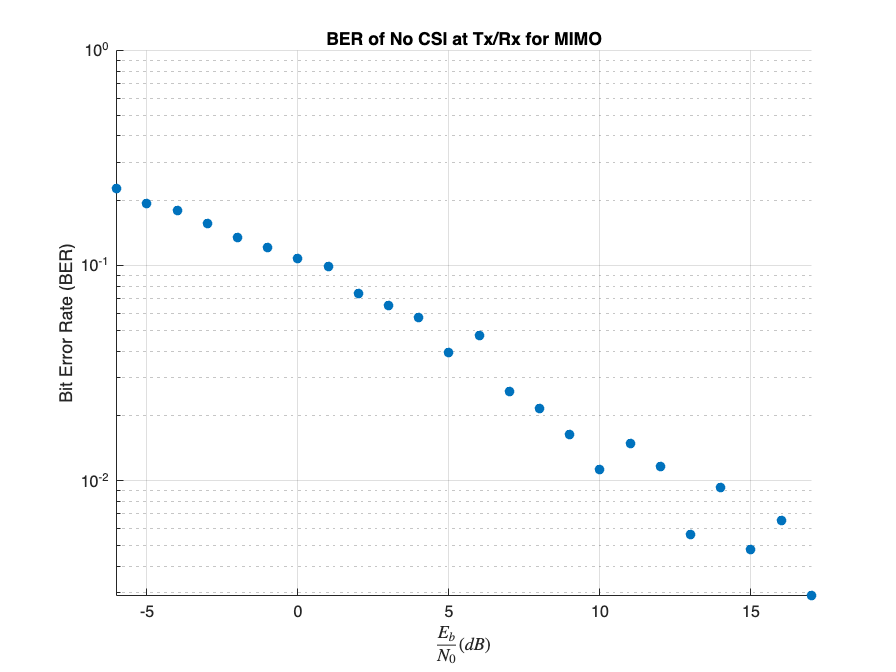


figure;
scatter(EbN0dB,ber9,'filled');
set(gca,'yscale','log')
xlim([-6 17])
ylim([0 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER of No CSI at Tx/Rx for MIMO');

#### Comparison of BER with Different Number of Pilot Vectors

From the equation $y_i =P_i \cdot h+n$, we see that a minimum of 4 pilot vectors is required to estimate the channel matrix H. The plot below shows that the BER for Npilot�=10, 20, 50, and 1000 are quite similar. To balance channel estimation accuracy with the overhead of pilot symbols, choosing Npilot�=20 is a practical compromise.

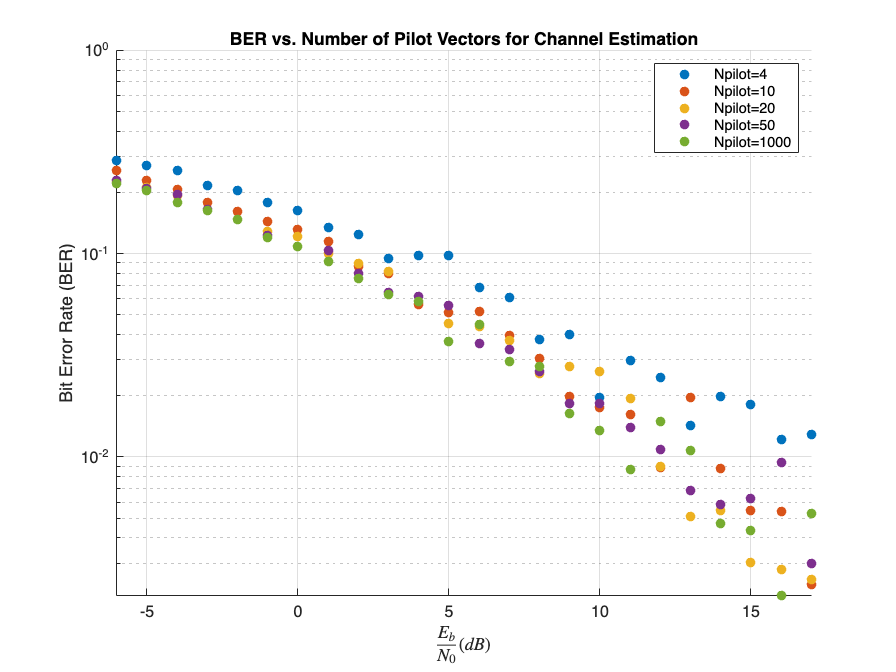

% transmitted data using QPSK modulation
Nbits=1e4;
bitvec=randi([0,1],[1,Nbits]);                                   % 1x10000
symvec=complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2); % 1x5000
txsyms=reshape(symvec,floor([Nt,length(symvec)/Nt]));            % 2x2500

close all;
figure;
number_of_pilot_vectors=[4 10 20 50 1000];
for n=1:length(number_of_pilot_vectors)
    Npilots=number_of_pilot_vectors(n); % number of (2x1) pilot vectors
    ber9=zeros(1,length(EsN0dB));
    ser9=zeros(1,length(EsN0dB));
    for i=1:length(EsN0dB)
        total_bit_error=0;
        total_symbol_error=0;
        nruns=100;
        for k=1:nruns
    
            H=sigfad*complex(randn(Nt,Nr),randn(Nt,Nr));
            % Channel Estimation           
            pilot_bits=randi([0,1],[1,2*(Nt*Npilots)]);
            pilot_symbols=complex(2*pilot_bits(1:2:end)-1,2*pilot_bits(2:2:end)-1)/sqrt(2); % 1x2000
            pilot_symbols=reshape(pilot_symbols,floor([Nt,length(pilot_symbols)/Nt]));      % 2x1000
            
            P=zeros(2*Npilots,4);
            for Np=1:Npilots % go through each pilot vector
                P((2*Np-1):2*Np,:)=[pilot_symbols(:,Np).' 0 0; 0 0 pilot_symbols(:,Np).'];
            end 
    
            noise_pilot=sqrt(N0(i))*complex(randn(2,Npilots),randn(2,Npilots)); % 2x1000
            y_pilot=H*pilot_symbols+noise_pilot;  % 2x1000
            y_pilot=reshape(y_pilot,[2*Npilots,1]);
            h=(P'*P+(1/SNR(i))*eye(4))\(P'*y_pilot);
            estimated_H=reshape(h,[Nt,Nr]).';
            
            % Transmit actual data
            noise=sqrt(N0(i))*complex(randn(size(txsyms)),randn(size(txsyms)));
            y=H*txsyms+noise;
            x_LMMSE=(estimated_H'*estimated_H+(1/SNR(i))*eye(2))\(estimated_H'*y); % 2x2500
            x_LMMSE=reshape(x_LMMSE,[1,length(symvec)]); % 1x5000
        
            [decoded_symbol_vector,decoded_bit_vector]=qpskdetect(x_LMMSE);
            total_bit_error=total_bit_error+sum(xor(bitvec',decoded_bit_vector))/Nbits;
            total_symbol_error=total_symbol_error+sum(symvec~=decoded_symbol_vector)/(Nbits/2);
        end 
        ber9(i)=total_bit_error/nruns;
        ser9(i)=total_symbol_error/nruns;
    end
    scatter(EbN0dB,ber9,'filled','DisplayName',sprintf('Npilot=%d',number_of_pilot_vectors(n)));
    hold on
end

set(gca,'yscale','log')
xlim([-6 17])
ylim([0 1])
grid on
hold off

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('BER vs. Number of Pilot Vectors for Channel Estimation');
legend;